# Derive and apply the rate Jacobian of a TRIPLE compound **Pendulum**

In this task we're going to derive and then implement the rate Jacobian for a TRIPLE compound pendulum.  The system that we're going to explore is shown below:

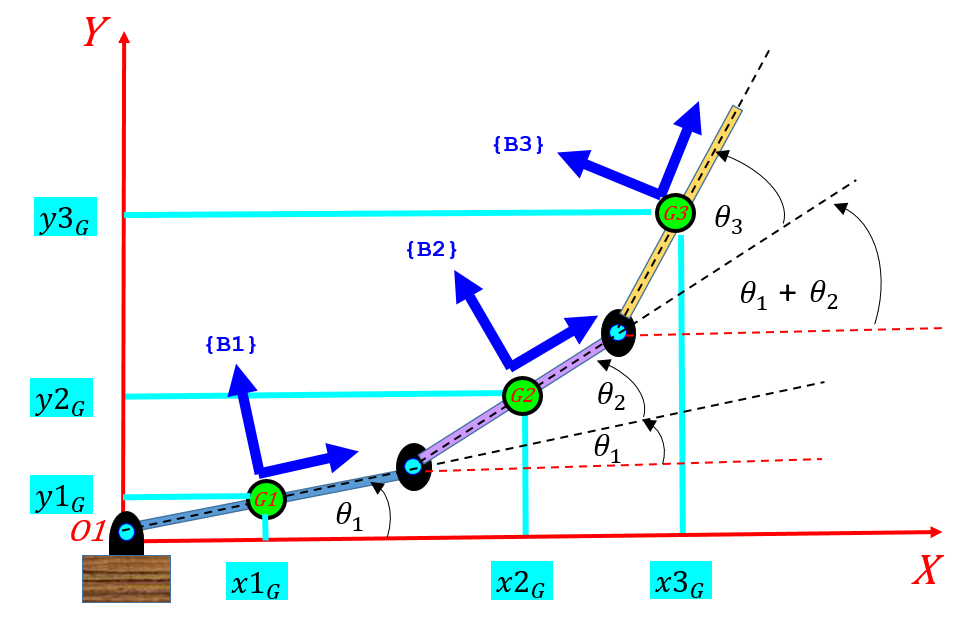     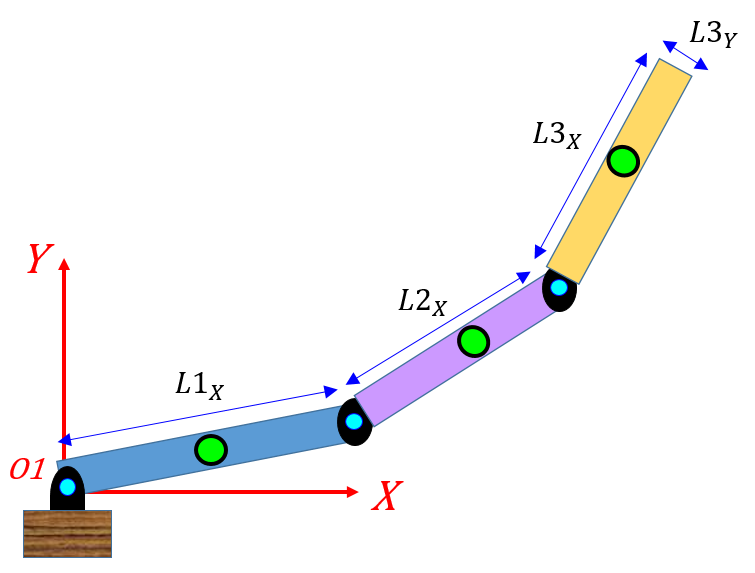

`Bradley Horton : 01-Aug-2016, bradley.horton@mathworks.com.au`      

## Defining some geometry parameters:

syms theta_1 theta_2 theta_3 L_1 L_2 L_3 
syms XE YE

## FORWARD Kinematics:  $\theta \longrightarrow f(\theta) \longrightarrow (X_E,Y_E)$

Define the X,Y position of the End effector:

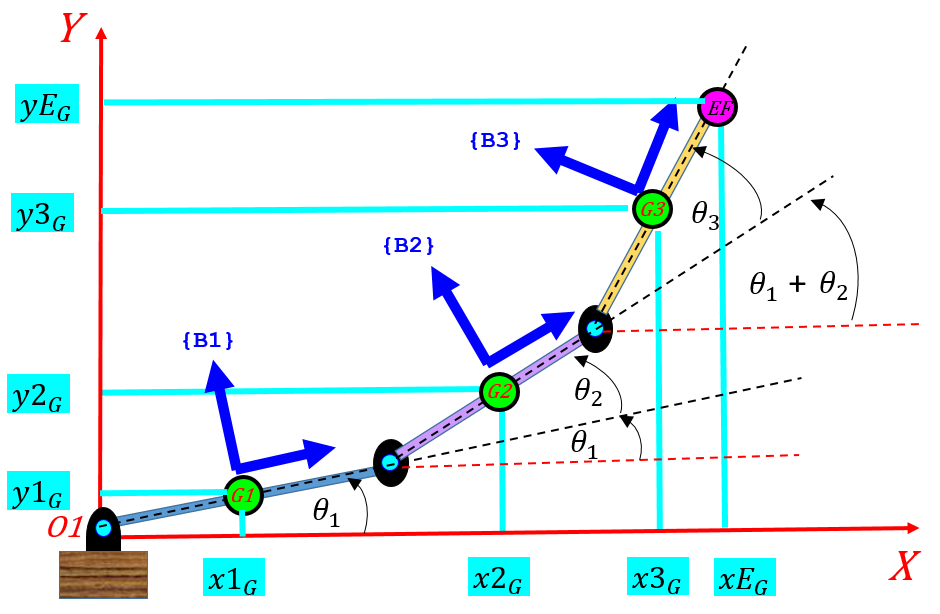

Here's are the **X** and **Y** co-ordinates of the end effector (EF):

th_12  = theta_1 + theta_2;
th_123 = theta_1 + theta_2 + theta_3;

the_XE_RHS = L_1*cos(theta_1) + L_2*cos(th_12) + L_3*cos(th_123);
the_YE_RHS = L_1*sin(theta_1) + L_2*sin(th_12) + L_3*sin(th_123);

And I can create a MATLAB function of these END EFFECTOR  forward kinematics:

matlabFunction([the_XE_RHS, the_YE_RHS], 'File', 'bh_xy_for_3link_planar')

## Compute our system Jacobian:

The system Jacobian is defined as:


$$J = \frac{d(X,Y)}{d(\theta_1, \theta_2, \theta_3)} = 
\pmatrix{
\frac{dX}{d\theta_1} & \frac{dX}{d\theta_2} 
& \frac{dX}{d\theta_3}  \cr
\frac{dY}{d\theta_1} & \frac{dY}{d\theta_2} 
& \frac{dY}{d\theta_3} \cr

}$$


the_J = jacobian( [the_XE_RHS, the_YE_RHS],[theta_1, theta_2, theta_3]  )

We can use the Jacobian in the following way:


$$\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt}
} = 

\pmatrix{
\frac{dX}{d\theta_1} & \frac{dX}{d\theta_2} 
& \frac{dX}{d\theta_3}  \cr
\frac{dY}{d\theta_1} & \frac{dY}{d\theta_2} 
& \frac{dY}{d\theta_3} \cr

} . 
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt} \cr
\frac{d\theta_3}{dt}
}$$



$$\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt}
} = 

J . 
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt} \cr
\frac{d\theta_3}{dt}
}$$


So we can then write:


$$
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt} \cr
\frac{d\theta_3}{dt}
} = 
J^{+} \enspace . \enspace  
\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt}
} 
\enspace \enspace \textstyle{where} \enspace J^+ \enspace \text{is the Moore-Penrose pseudoinverse of J}$$
 

We can convert the symbolic expression of the Jacobian into a MATLAB function block

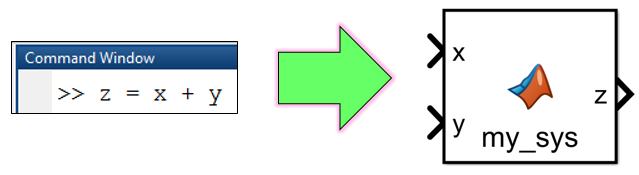

tf_i_should_create_SL_block = true;
if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_ikin_3dof';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
                  
    % convert J into a MATLAB function block(MLF)
    matlabFunctionBlock( [MODEL_NAME,'/THE_J'], ...
                         the_J, ...
                         'Optimize', false  );
    % why not convert the FORWARD kinematic expressions 
    % into MLF blocks too !                     
    matlabFunctionBlock( [MODEL_NAME,'/THE_XEYE'], ...
                         the_XE_RHS, the_YE_RHS, ...
                         'Optimize', false, ...
                         'Outputs', {'XE', 'YE'}   );                           
end

## Apply these concepts:

bh_parameters_for_TRIPLE_compound_pendulum

theta1_0     =  0;                    % rad
theta1_dot_0 =  0;                    % rad/sec 
theta2_0     =  0;                    % rad
theta2_dot_0 =  0;                    % rad/sec
theta3_0     =  0;                    % rad
theta3_dot_0 =  0;              

In the Simulink model `<bh_test_J_TRI_pend.slx>` we've applied the expressions that we derived earlier for the Jacobian and the FORWARD kinematics.  They look like this:

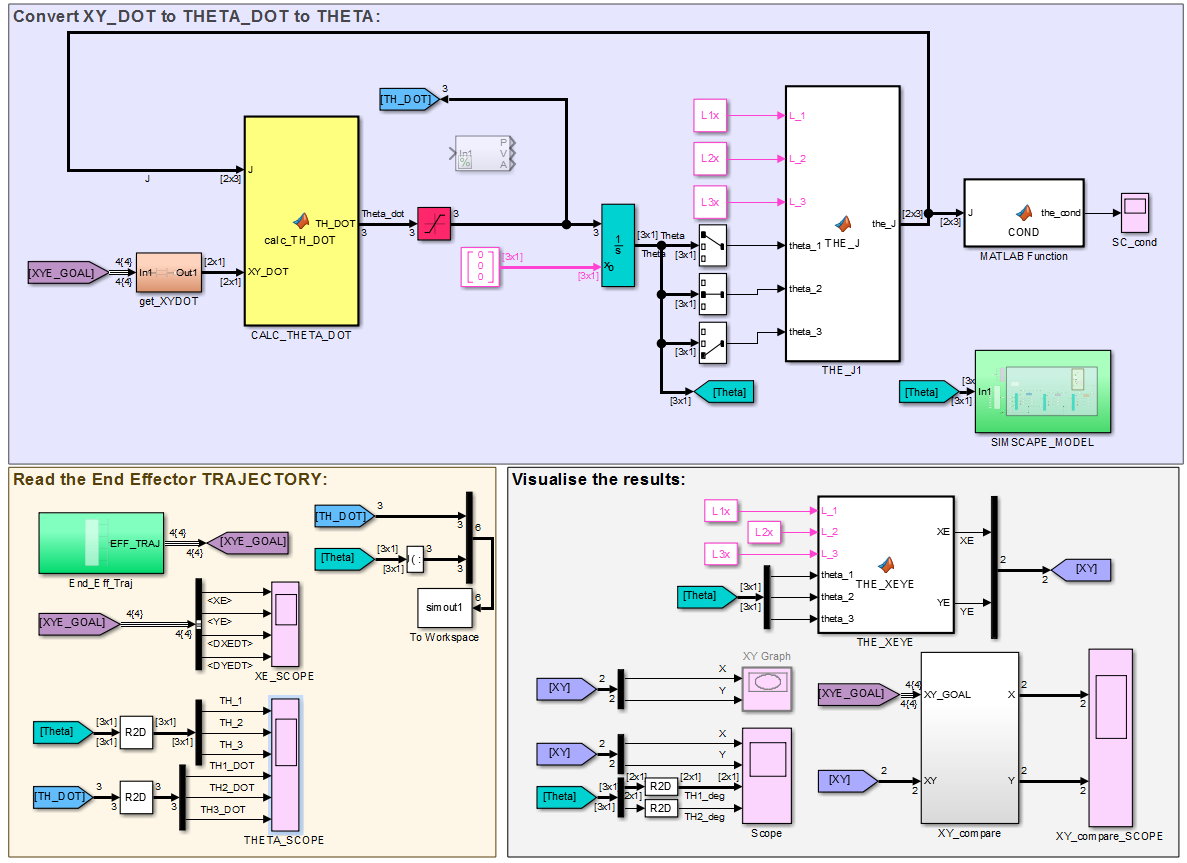

Note that the blocks above, are implementing our previouslly derived equation of:


$$
\pmatrix{
\frac{d\theta_1}{dt} \cr
\frac{d\theta_2}{dt} \cr
\frac{d\theta_3}{dt}
} = 
J^{+} \enspace . \enspace  
\pmatrix{
\frac{dX}{dt} \cr
\frac{dY}{dt}
} $$


In this model, here's what the $\dot{X}_E$ and $\dot{Y}_E$signals look like - these end effector velocities are defined in an EXCEL file called <`bh_hello_complete.xlsx`>, which we read within the Simulink model.

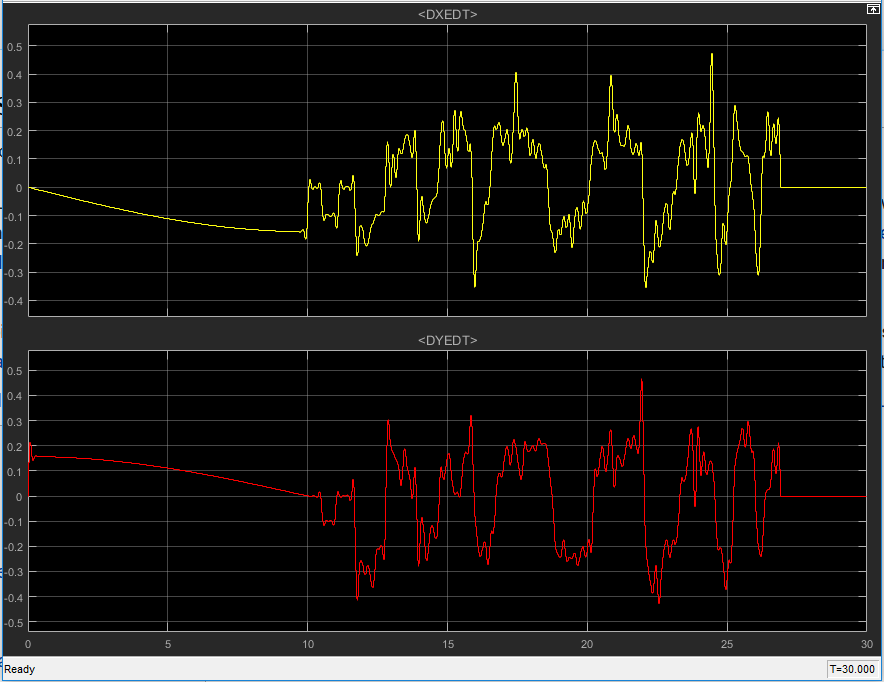

And here's what the signals for {$X_E, Y_E, \theta_1, \theta_2, \theta_3$} look like:

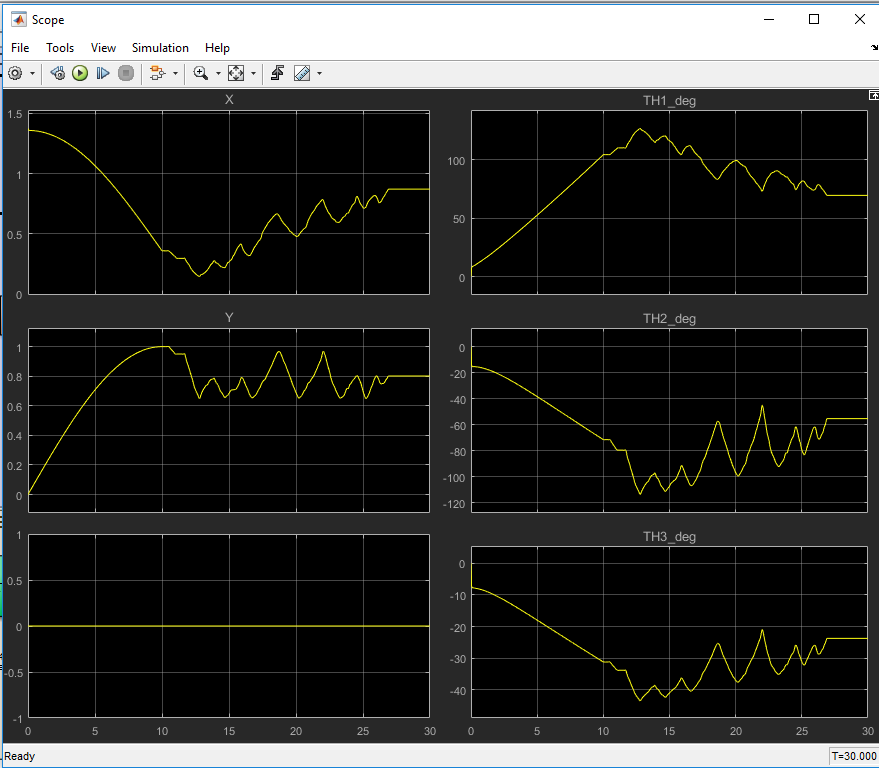

So ? - So when you plot $X_E$ with $Y_E$ you get this:

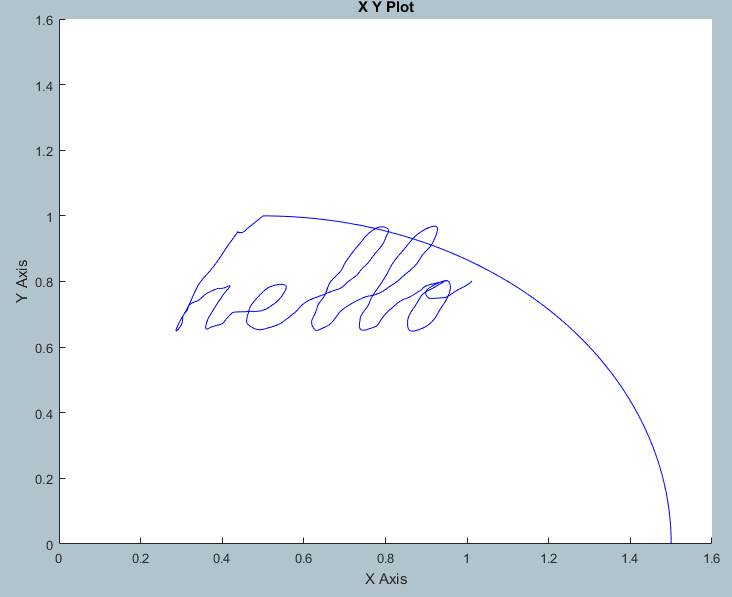

## View the kinematics:

In the same Simulink model mentioned above, I have a Simscape model that will allow you to see an animation of the 3 link manipulator - so check that out: